# Asesoria

### Metodos Numericos

#### 2022-2S : 28/11/2022

clear

F = @(t, U) [-.03*U(1).*U(2) - .01*U(1), ...
             .03*U(1).*U(2) - .005*U(2), ...
             .005*U(2) + .01*U(1)];

Za = [80 2 0]; a = 0; b = 300; M = 300;

[T, U] = rks4(F, a, b, Za, M);
U = round(U);
tabla = array2table(U, 'VariableNames', ["S", "I", "R"])
[T', U(:, :)]
dI = diff(U(:, 2));

tabla = 301×3 table
    S     I     R
    __    __    _

    80     2    0
    64    17    1
    21    59    1
     8    72    2
     4    75    2
     2    77    3
     1    78    3
     1    78    3
     0    78    4
     0    78    4
     0    77    5
     0    77    5
     0    77    5
     0    76    6
     0    76    6
     0    75    7


reference = [T(2:end)', dI];

ans =      0    80     2     0
     1    64    17     1
     2    21    59     1
     3     8    72     2
     4     4    75     2
     5     2    77     3
     6     1    78     3
     7     1    78     3
     8     0    78     4
     9     0    78     4


maxI = max(dI);
reference(dI == maxI, :)

clear


ans =      2    42


help poisson
a = 0; b = 1; c = a; d = b;
h = 1/4; k = h; m = (b - a)/h +1; n = m;


  poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)
  en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos
  g funcion creada con @
  f1 es la condicion de frontera abajo (en y=c) funcion creada con @
  f2 es la condicion de frontera derecha (en x=b) funcion creada con @
  f3 es la condicion de frontera arriba (en y=d) funcion creada con @
  f4 es la condicion de frontera izquierda (en x=a) funcion creada con @
  Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres
  m es el numero de puntos sobre el eje x
  n es el numero de puntos sobre el eje y



f1 = @(x) x.^3;
f2 = @(y) 1*ones(size(y));
f3 = @(x) x.^3;
f4 = @(y) 0*y;
g = @(x, y) y;

f2([1 2 3])

U = poisson(g, f1, f2, f3, f4, a, b, c, d, m, n)
U(1 +1, 1 +2) % U(1 + no. pasos en y, 1 + no. pasos en x)

ans =      1     1     1


U = U'
U(1 + 2, 1 +1)

U =          0    0.0156    0.1250    0.4219    1.0000
         0    0.0951    0.2684    0.5684    1.0000
         0    0.1122    0.3008    0.5988    1.0000
         0    0.0840    0.2550    0.5572    1.0000
         0    0.0156    0.1250    0.4219    1.0000


clear

ans = 0.2684

U =          0         0         0         0         0
    0.0156    0.0951    0.1122    0.0840    0.0156
    0.1250    0.2684    0.3008    0.2550    0.1250
    0.4219    0.5684    0.5988    0.5572    0.4219
    1.0000    1.0000    1.0000    1.0000    1.0000


D1 = @(t, U) [U(2), -(1 + t).*U(2) + 2*U(1) + (1 - t.^2).*exp(-t)];

ans = 0.2684

D2 = @(t, U) [U(2), -(1 + t).*U(2) + 2*U(1)];

[T, U] = rks4(D1, 0, 1, [-.5 0], 20);
[~, V] = rks4(D2, 0, 1, [0 1], 20);
U = U(:, 1); V = V(:, 1);

coef = (0 - U(end)) / V(end)
X = U + coef*V

clear

F = @(t, y) exp(-t) + cos(t - y);

coef = 0.8434

a = 4; b = 7; h = .15; M = (b - a) / h, ya = -1.5;

X =    -0.5000
   -0.4589
   -0.4198
   -0.3826
   -0.3474
   -0.3139
   -0.2823
   -0.2524
   -0.2241
   -0.1975


[T, AB] = adamBashforth4(F, a, b, ya, M)
AB(T == 4.45), AB(T == 5.2), AB(T == 6.25), AB(T == 6.7), AB(T == 7)

clear


M = 20

F = @(t, Y) [Y(2), exp(t/3) - 6*Y(2) + Y(1) / 25];

T =     4.0000    4.1500    4.3000    4.4500    4.6000    4.7500    4.9000    5.0500    5.2000    5.3500    5.5000    5.6500    5.8000    5.9500    6.1000    6.2500    6.4000    6.5500    6.7000    6.8500    7.0000


AB =    -1.5000
   -1.3890
   -1.2746
   -1.1572
   -1.0371
   -0.9147
   -0.7902
   -0.6638
   -0.5356
   -0.4060


a = 0; b = 6; h = .5; M = (b - a) / h; Ya = [1 .28];

ans = -1.1572

ans = -0.5356

ans = 0.3967

ans = 0.8099

ans = 1.0886


[T, Y] = rks4(F, a, b, Ya, M)
V = Y(:, 2); Y = Y(:, 1);
Y(T == 6), V(T == 6)

clear
syms r a real


T =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000


Y =     1.0000    0.2800
    1.0818    0.3546
    1.1766    0.4520
    1.2861    0.5800
    1.4121    0.7489
    1.5566    0.9731
    1.7214    1.2720
    1.9079    1.6720
    2.1170    2.2093
    2.3489    2.9338


a = 1
Eq(r) = 2*r - 14/(3*a)*r^2 + 40/27 * r^3 / a^2 - 72/(3*27)*r^4/a^3 + ...

ans = 3.1512

ans = 7.0476

    72/27^2 * r^5 / a^4 - 8 / (3*27^2) * r^6 / a^4;

clf('reset')
fplot(Eq(r), [0, .5])

syms f(t)

a = 1

f(t) = R1(4,2)+((t-R1(6,2))./R2(6,2)).*R2(4,2);
a = eval(solve(f == 0.6758,t)) % Punto hecho netamente con Matlab
b = R1(6,2)+(R2(6,2).*(0.6758-R1(4,2)./R2(6,2))) % Despeje manual

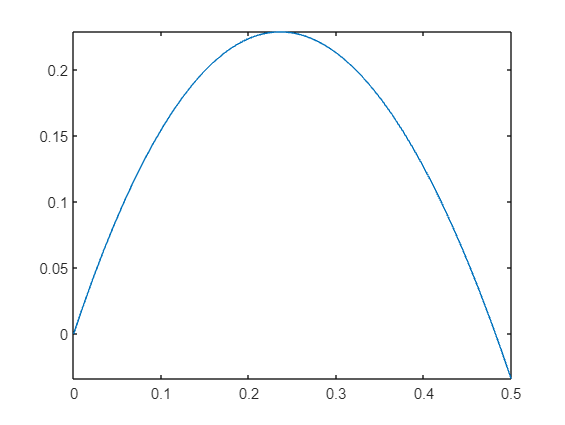

clear
format short


F1 = @(x,u) [u(2), (-exp(-x).*u(2)+atan(x).*u(1)+cos(x))./3];
F2 = @(x,u) [u(2), (-exp(-x).*u(2)+atan(x).*u(1))./3];


a = 0.7710

a = 1; b = 2.2; M = 5;

b = 1.5616


[T R1] = rks4(F1,a,b,[5 0],M);
[T R2] = rks4(F2,a,b,[0 1],M);
R1 = [T' R1]    
R2 = [T' R2]
R1(4,2)

syms f(t)
f(t) = R1(4,2)+((t-R1(6,2))./R2(6,2)).*R2(4,2);
a = eval(solve(f == 0.6758,t)) % Punto hecho netamente con Matlab
b = R1(6,2)+(R2(6,2)*((0.6758-R1(4,2))/R2(4,2))) % Despeje manual

function  [T, AB] = adamBashforth4 (f, a, b, ya, M)

R1 =     1.0000    5.0000         0
    1.2400    5.0437    0.3676
    1.4800    5.1780    0.7551
    1.7200    5.4079    1.1652
    1.9600    5.7396    1.6040
    2.2000    6.1809    2.0812


R2 =     1.0000         0    1.0000
    1.2400    0.2374    0.9823
    1.4800    0.4734    0.9888
    1.7200    0.7140    1.0207
    1.9600    0.9655    1.0794
    2.2000    1.2344    1.1669


% Entrada  - f funcion creada con @

ans = 5.4079

%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - E = [T', Y'] donde T es el vector de abscisas y

a = -2.0000

%            Y es el vector de ordenadas

b = -2.0000


%  METODOS NUMERICOS: Programas en Matlab
% (c) 2004 por John H. Mathews y Kurtis D. Fink
%  Software complementario acompa�ando al texto:
%  METODOS NUMERICOS con Matlab, Cuarta Edicion
%  ISBN: 0-13-065248-2
%  Prentice-Hall Pub. Inc.
%  One Lake Street
%  Upper Saddle River, NJ 07458

h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;

for j = 1:3
    f1 = feval(f, T(j), Y(j));
    Y(j +1) = Y(j) + h*feval(f, T(j) + h/2, Y(j) + 1/2*h*f1);
end

for  k = 4:M
   f1 = feval(f, T(k), Y(k));
   f2 = feval(f, T(k -1), Y(k -1));
   f3 = feval(f, T(k -2), Y(k -2));
   f4 = feval(f, T(k -3), Y(k -3));
   Y(k +1) = Y(k) + h/24 * (55*f1 - 59*f2 + 37*f3 - 9*f4);
end

AB = Y';

end

function  [T, Y] = milne (f, a, b, ya, M)

% Entrada  - f funcion creada con @
%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - E = [T', Y'] donde T es el vector de abscisas y
%            Y es el vector de ordenadas

%  METODOS NUMERICOS: Programas en Matlab
% (c) 2004 por John H. Mathews y Kurtis D. Fink
%  Software complementario acompa�ando al texto:
%  METODOS NUMERICOS con Matlab, Cuarta Edicion
%  ISBN: 0-13-065248-2
%  Prentice-Hall Pub. Inc.
%  One Lake Street
%  Upper Saddle River, NJ 07458

h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;

for k = 1:3
    f1 = feval(f, T(k), Y(k));
    f2 = feval(f, T(k) + 2/3 * h, Y(k) + 2/3*h * f1);
    Y(k + 1) = Y(k) + h/4 * (f1 + 3*f2);
end

for  j = 4:M
    f1 = feval(f, T(j), Y(j));
    f2 = feval(f, T(j -1), Y(j -1));
    f3 = feval(f, T(j -2), Y(j -2));
    Y(j+1) = Y(j-3) + 4/3 * h * (2 * f1 - f2 + 2*f3);
end

T = T'; Y = Y';

end